clear; clc; close all;

%Load signals
edfFilename = 'R1.edf';
[hdr, record1] = edfread(edfFilename);

Step 1
Reading requested records. (This may take a few minutes.)...
Step 2
Parsing data...


edfFilename = 'R2.edf';
[~, record2] = edfread(edfFilename);

Step 1
Reading requested records. (This may take a few minutes.)...
Step 2
Parsing data...


edfFilename = 'R3.edf';
[~, record3] = edfread(edfFilename);

Step 1
Reading requested records. (This may take a few minutes.)...
Step 2
Parsing data...


edfFilename = 'R4.edf';
[~, record4] = edfread(edfFilename);

Step 1
Reading requested records. (This may take a few minutes.)...
Step 2
Parsing data...


edfFilename = 'R5.edf';
[~, record5] = edfread(edfFilename);

Step 1
Reading requested records. (This may take a few minutes.)...
Step 2
Parsing data...


## Get all segements of the signals LEFT EOG

EOGL_R1 = record1(6, 1:length(record1));
EOGL_R1 = EOGL_R1';
EOGL_R2 = record2(6, 1:length(record2)); 
EOGL_R2 = EOGL_R2';
EOGL_R3 = record3(6, 1:length(record3)); 
EOGL_R3 = EOGL_R3';
EOGL_R4 = record4(6, 1:length(record4)); 
EOGL_R4 = EOGL_R4';
EOGL_R5 = record5(6, 1:length(record5)); 
EOGL_R5 = EOGL_R5';


## Get all segements of the signals RIGHT EOG

EOGR_R1 = record1(7, 1:length(record1));
EOGR_R1 = EOGR_R1';
EOGR_R2 = record2(7, 1:length(record2)); 
EOGR_R2 = EOGR_R2';
EOGR_R3 = record3(7, 1:length(record3)); 
EOGR_R3 = EOGR_R3';
EOGR_R4 = record4(7, 1:length(record4)); 
EOGR_R4 = EOGR_R4';
EOGR_R5 = record5(7, 1:length(record5)); 
EOGR_R5 = EOGR_R5';


## Difference between left and right eye

% d1=EOGL_R1-EOGR_R1;
% d2=EOGL_R2-EOGR_R2;
% d3=EOGL_R3-EOGR_R3;
% d4=EOGL_R4-EOGR_R4;
% d5=EOGL_R5-EOGR_R5;

## Preprocessing

preprocessed_EOGL_R1 = preprocess(EOGL_R1);
preprocessed_EOGL_R2 = preprocess(EOGL_R2);
preprocessed_EOGL_R3 = preprocess(EOGL_R3);
preprocessed_EOGL_R4 = preprocess(EOGL_R4);
preprocessed_EOGL_R5 = preprocess(EOGL_R5);

preprocessed_EOGR_R1 = preprocess(EOGR_R1);
preprocessed_EOGR_R2 = preprocess(EOGR_R2);
preprocessed_EOGR_R3 = preprocess(EOGR_R3);
preprocessed_EOGR_R4 = preprocess(EOGR_R4);
preprocessed_EOGR_R5 = preprocess(EOGR_R5);


## Arrange dataset

epoch_EOGL_R1 = arrangeDataECG(preprocessed_EOGL_R1); 
epoch_EOGL_R2 = arrangeDataECG(preprocessed_EOGL_R2); 
epoch_EOGL_R3 = arrangeDataECG(preprocessed_EOGL_R3);
epoch_EOGL_R4 = arrangeDataECG(preprocessed_EOGL_R4);
epoch_EOGL_R5 = arrangeDataECG(preprocessed_EOGL_R5);

%Number of samples for each recording
nSamplesL = [height(epoch_EOGL_R1);height(epoch_EOGL_R2);height(epoch_EOGL_R3);...
    height(epoch_EOGL_R4);height(epoch_EOGL_R5)];

epoch_EOGR_R1 = arrangeDataECG(preprocessed_EOGR_R1); 
epoch_EOGR_R2 = arrangeDataECG(preprocessed_EOGR_R2); 
epoch_EOGR_R3 = arrangeDataECG(preprocessed_EOGR_R3);
epoch_EOGR_R4 = arrangeDataECG(preprocessed_EOGR_R4);
epoch_EOGR_R5 = arrangeDataECG(preprocessed_EOGR_R5);

%Number of samples for each recording
nSamplesR = [height(epoch_EOGR_R1);height(epoch_EOGR_R2);height(epoch_EOGR_R3);...
    height(epoch_EOGR_R4);height(epoch_EOGR_R5)];

## Create delta EOG

d1= epoch_EOGL_R1-epoch_EOGR_R1;
d2= epoch_EOGL_R2-epoch_EOGR_R2;
d3= epoch_EOGL_R3-epoch_EOGR_R3;
d4= epoch_EOGL_R4-epoch_EOGR_R4;
d5= epoch_EOGL_R5-epoch_EOGR_R5;

## Feature extraction (first left then right and then delta)

eogf_1 = extractFeaturesEOG(epoch_EOGL_R1,epoch_EOGR_R1,d1);
eogf_2 = extractFeaturesEOG(epoch_EOGL_R2,epoch_EOGR_R2,d2);
eogf_3 = extractFeaturesEOG(epoch_EOGL_R3,epoch_EOGR_R3,d3);
eogf_4 = extractFeaturesEOG(epoch_EOGL_R4,epoch_EOGR_R4,d4);
eogf_5 = extractFeaturesEOG(epoch_EOGL_R5,epoch_EOGR_R5,d5);

## Correlation coefficients

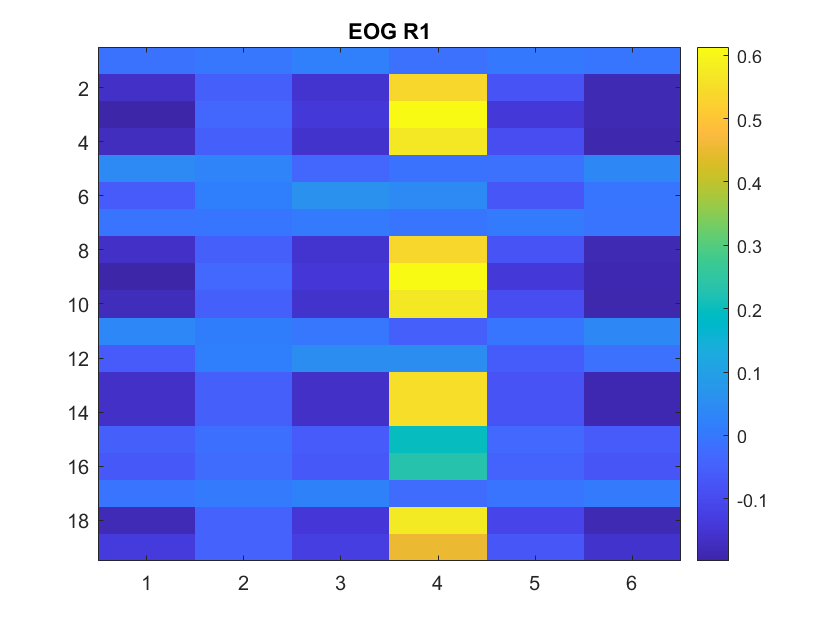

taskf('R1.xml', eogf_1, "EOG R1");

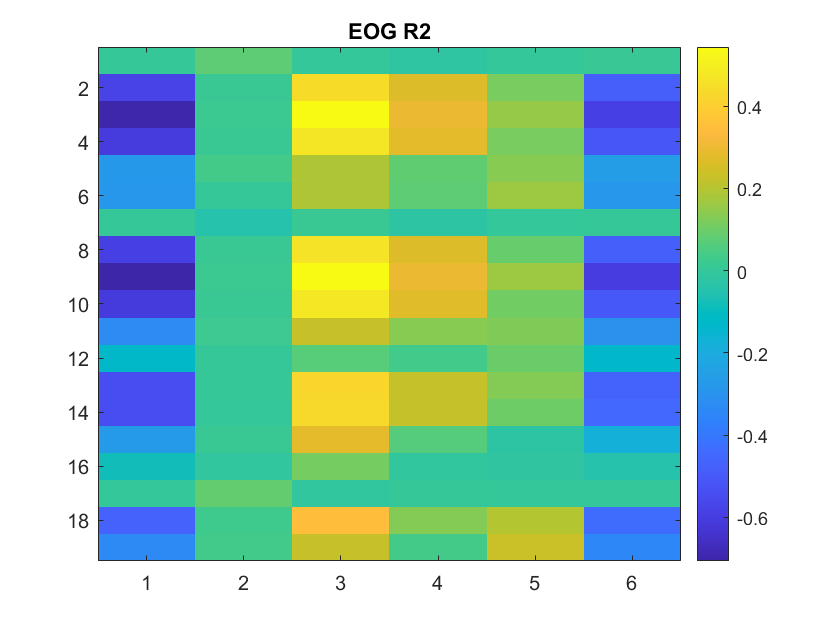

taskf('R2.xml', eogf_2, "EOG R2");

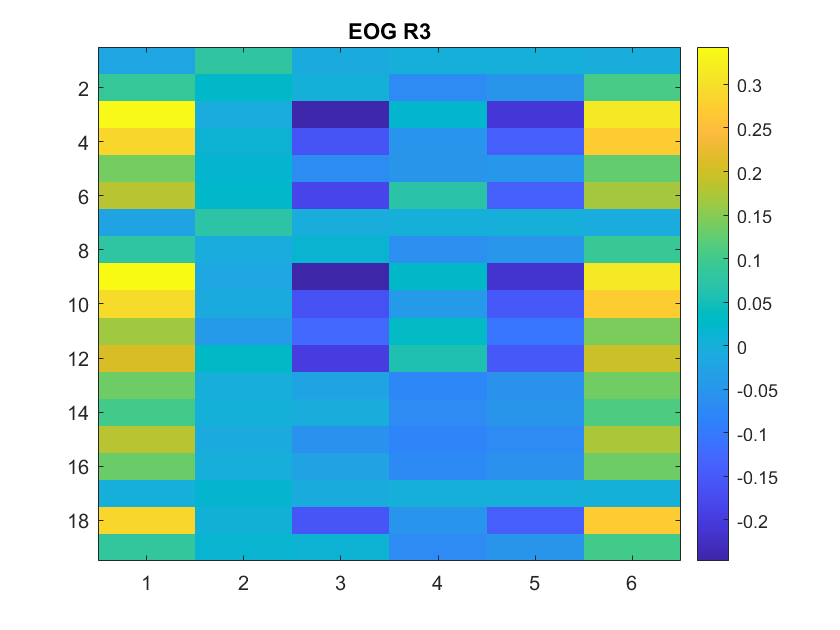

taskf('R3.xml', eogf_3, "EOG R3");

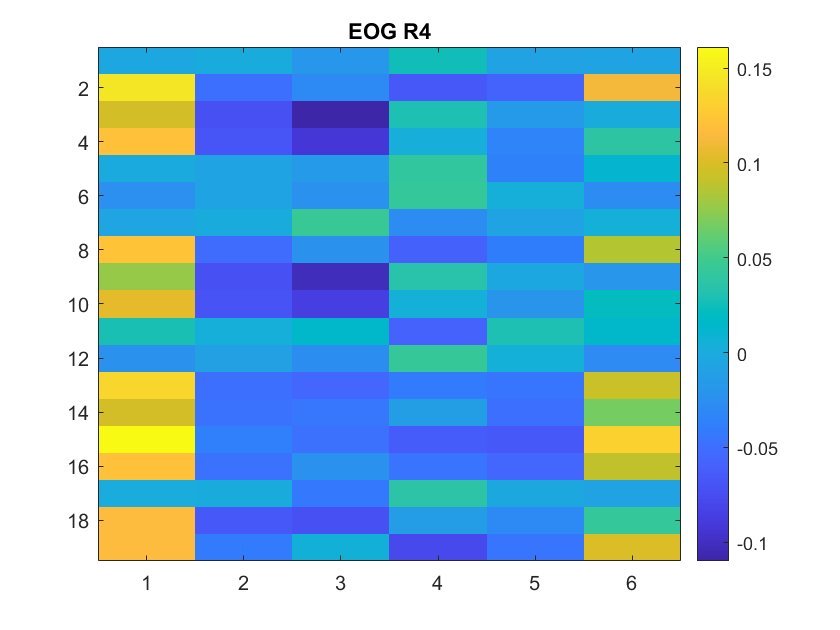

taskf('R4.xml', eogf_4, "EOG R4");

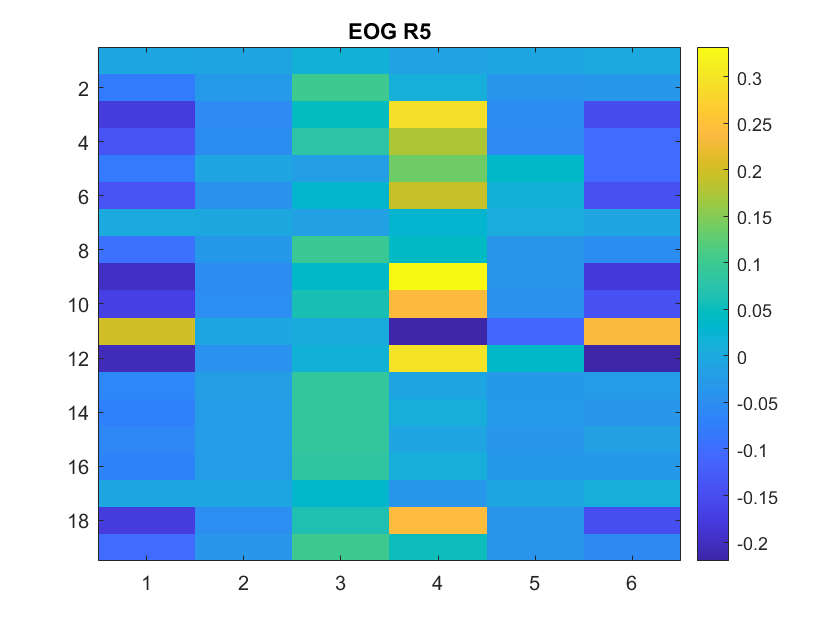

taskf('R5.xml', eogf_5, "EOG R5");